# Center Image on a Page

This example shows how to center an image on a landscape page for PDF and Microsoft® Word reports.

The example creates a Report API report having landscape layout and uses the `centerImage` local function to add the images at the center of the page.

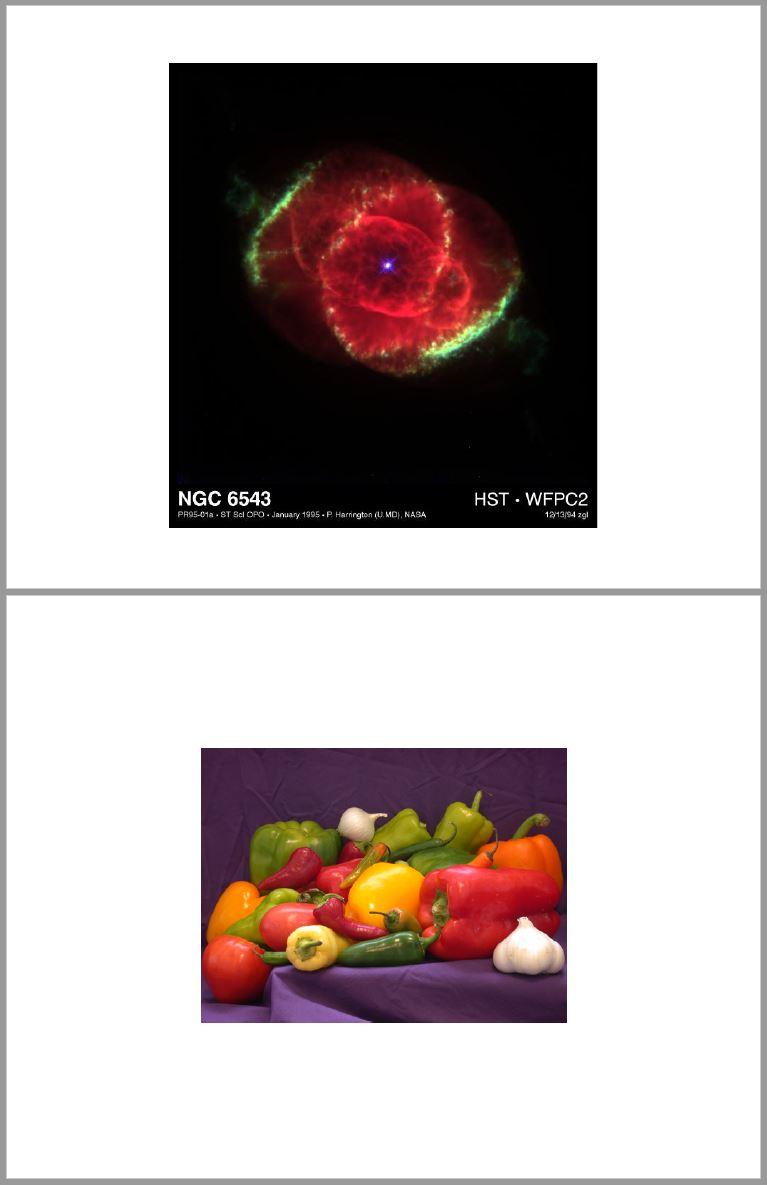

## Create Report

Import the DOM and Report API packages so that you do not have to use long, fully-qualified class names.

import mlreportgen.dom.*
import mlreportgen.report.*

Create a PDF report. To create a Microsoft® Word report, change "`pdf"` to "`docx"`.

rpt = Report("myreport","pdf");
open(rpt);

## Update Report Page Layout

Create a page layout object.

if strcmpi(rpt.Type,"pdf")
    pageLayoutObj = PDFPageLayout;
else
    pageLayoutObj = DOCXPageLayout;
end

Specify the page orientation, height, and width.

pageLayoutObj.PageSize.Orientation = "landscape";
pageLayoutObj.PageSize.Height = "8.5in";
pageLayoutObj.PageSize.Width = "11in";

Specify the page margins.

pageLayoutObj.PageMargins.Top = "0.5in";
pageLayoutObj.PageMargins.Bottom = "0.5in";
pageLayoutObj.PageMargins.Left = "0.5in";
pageLayoutObj.PageMargins.Right = "0.5in";

pageLayoutObj.PageMargins.Header = "0.3in";
pageLayoutObj.PageMargins.Footer = "0.3in";

Add the page layout object to the report.

add(rpt,pageLayoutObj);

## Add Images

Call the `centerImage` local function to add the images at the center of the page.

centerImage(which("ngc6543a.jpg"),rpt);

centerImage(which("peppers.png"),rpt);

## Generate the Report

Close and view the report.

close(rpt);
rptview(rpt);

## The `centerImage` Local Function

This function adds the specified image at the center of the page in the specified report. The function uses the DOM `Image` to wrap the image file and an invisible DOM `Table` to do the layout.

function centerImage(imageFile,rpt)

Import the DOM API and report generator utility packages so that you do not have to use long, fully-qualified class names.

    import mlreportgen.dom.*
    import mlreportgen.utils.*

Get the report's current page layout to determine the current page size and the page margins. The page layout information is used to calculate the page body size in order to size the layout table created in a subsequent step.

    pageLayout = getReportLayout(rpt);
    pageSize = pageLayout.PageSize;
    pageMargins = pageLayout.PageMargins;

Calculate the page body width. The page body width denotes the page width available for the content and is determined by subtracting the left and right margin size from the page width. For DOCX output, gutter size also needs to be subtracted.

    bodyWidth = units.toInches(pageSize.Width) - ...
        units.toInches(pageMargins.Left) - ...
        units.toInches(pageMargins.Right);
    
    if strcmpi(rpt.Type,"docx")
        bodyWidth = bodyWidth - ...
            units.toInches(pageMargins.Gutter);
    end
    bodyWidth = sprintf("%0.2fin",bodyWidth);

Calculate the page body height. The page body height denotes the page height available for the content and is determined by subtracting the top and bottom margin size from the page height. For PDF output, the header and footer sizes also need to be subtracted because the body extends from the bottom of the header to the top of the footer.

    bodyHeight = units.toInches(pageSize.Height) - ...
        units.toInches(pageMargins.Top) - ...
        units.toInches(pageMargins.Bottom);
    
    if strcmpi(rpt.Type,"pdf")
        bodyHeight = bodyHeight - ...
            units.toInches(pageMargins.Header) - ...
            units.toInches(pageMargins.Footer);
    end
    bodyHeight = sprintf("%0.2fin",bodyHeight);

Create an `Image` object wrapped around the image file. Scale the image to fit the entry of the layout table created in a subsequent step.

    image = Image(imageFile);
    image.Style = [image.Style {ScaleToFit}];

Wrap the image in a paragraph because PDF requires that an image reside in a paragraph. Update the paragraph style to make sure that there is no white space around the image.

    para = Paragraph(image);
    para.Style = [para.Style {OuterMargin("0in","0in","0in","0in")}];

Add the paragraph that contains the image in a 1-by-1 invisible layout table (`lo_table`). A table is considered invisible when the borders are not defined for the table and its table entries.

    lo_table = Table({para});

Span the table to the available page body width.

    lo_table.Width = bodyWidth;

Span the only table entry to the available page body height. Also, specify the vertical and horizontal alignment formats to make sure that the image is centered both vertically and horizontally inside the table entry.

    lo_table.TableEntriesStyle = [lo_table.TableEntriesStyle ...
        { ...
        Height(bodyHeight), ...
        HAlign("center"), ...
        VAlign("middle") ...
        }];

Add the layout table to the report.

    add(rpt,lo_table);
end

*Copyright 2019 The MathWorks, Inc.*